Print the networked system

clear all
close all
clc
load jPaperDataSimulation.mat

% Diagonal matrices out of Network Matrices: A,B,C,D,E,F,G,H,J,Q,S,R 
% (1 if true, -1 % if zero and 0 if false)
% diags = [0,1,1,-1,0,1,1,1,1]; % respectively for 
for i = 1:1:length(network.subsystems)
    format = '%.3f';
    format2 = '%.3f';
    strTemp = "\dot{x}_"+num2str(i)+" = ";
    disp(['A_ij Matrices for i = ',num2str(i)])
    for j = 1:1:length(network.subsystems)
%         disp(['Agent i=',num2str(i),' connect to agent j=',num2str(j)])
        network.subsystems(i).A{j};
        A_ij = network.subsystems(i).A{j}';
        A_ijAll = A_ij(:);
        if all(A_ijAll==0)
            continue
        end
        strTemp = strTemp + "\bm{ "; 
        strTemp = strTemp + num2str(A_ijAll(1),format) + " & " + num2str(A_ijAll(2),format) + " \\ " + num2str(A_ijAll(3),format) + " & " + num2str(A_ijAll(4),format); 
        strTemp = strTemp + "} x_"+num2str(j) + " + ";
%         disp(strTemp)
    end
    
    disp(['B_ii Matrices for i = ',num2str(i)])
    B_ii = network.subsystems(i).B{i}(:);
    strTemp = strTemp + "\bm{" + num2str(B_ii(1),format) + " \\ " + num2str(B_ii(2),format) + "} u_"+num2str(i)+" + ";
%     disp(strTemp)
    
    disp(['E_ij Matrices for i = ',num2str(i)])
    for j = 1:1:length(network.subsystems)
%         disp(['Agent i=',num2str(i),' connect to agent j=',num2str(j)])
        E_ij = network.subsystems(i).E{j};
        if all(E_ij==0)
            continue
        end
        strTemp = strTemp + "\bm{ " + num2str(E_ij(1),format2) + " \\ " + num2str(E_ij(2),format2) + "} w_"+num2str(j) + " + ";
    end
    disp(strTemp)
    
    
    strTemp = "y_"+num2str(i)+" = ";
    disp(['C_ii Matrices for i = ',num2str(i)])
    C_ii = network.subsystems(i).C{i}(:);
    strTemp = strTemp + "\bm{" + num2str(C_ii(1),format) + " & " + num2str(C_ii(2),format) + "} x_"+num2str(i)+" + ";
%     disp(strTemp)
    
    disp(['F_ii Matrices for i = ',num2str(i)])
    F_ii = network.subsystems(i).F{i}(:);
    strTemp = strTemp + "\bm{" + num2str(F_ii(1),format2) + "} w_"+num2str(i);
    disp(strTemp)
    
    
    strTemp = "z_"+num2str(i)+" = ";
    disp(['G_ii Matrices for i = ',num2str(i)])
    G_ii = network.subsystems(i).G{i}(:);
    strTemp = strTemp + "\bm{" + num2str(G_ii(1),format) + " & " + num2str(G_ii(2),format) + "} x_"+num2str(i)+" + ";
%     disp(strTemp)
    
    disp(['H_ii Matrices for i = ',num2str(i)])
    H_ii = network.subsystems(i).H{i}(:);
    strTemp = strTemp + "\bm{" + num2str(H_ii(1),format) + "} u_"+num2str(i)+" + ";
%     disp(strTemp)
    
    disp(['J_ii Matrices for i = ',num2str(i)])
    J_ii = network.subsystems(i).J{i}(:);
    strTemp = strTemp + "\bm{" + num2str(J_ii(1),format2) + "} w_"+num2str(i);
    disp(strTemp)
end

A_ij Matrices for i = 1


B_ii Matrices for i = 1


E_ij Matrices for i = 1


\dot{x}_1 = \bm{ 0.198 & 3.412 \\ -3.412 & 0.198} x_1 + \bm{ -0.114 & -0.038 \\ -0.038 & -0.073} x_2 + \bm{ -0.060 & -1.032 \\ 1.032 & -0.060} x_4 + \bm{0.000 \\ 0.905} u_1 + \bm{ 0.000 \\ -0.013} w_1 + \bm{ 0.000 \\ 0.003} w_2 + \bm{ -0.001 \\ 0.006} w_4 + 


C_ii Matrices for i = 1


F_ii Matrices for i = 1


y_1 = \bm{1.114 & -2.429} x_1 + \bm{0.000} w_1


G_ii Matrices for i = 1


H_ii Matrices for i = 1


J_ii Matrices for i = 1


z_1 = \bm{1.000 & 1.000} x_1 + \bm{1.000} u_1 + \bm{1.000} w_1


A_ij Matrices for i = 2


B_ii Matrices for i = 2


E_ij Matrices for i = 2


\dot{x}_2 = \bm{ -0.000 & -0.001 \\ -0.001 & -0.194} x_1 + \bm{ 1.547 & 3.164 \\ -3.164 & 1.547} x_2 + \bm{ -0.258 & -0.008 \\ -0.008 & -0.204} x_4 + \bm{-0.902 \\ 0.000} u_2 + \bm{ -0.004 \\ -0.010} w_1 + \bm{ -0.000 \\ 0.021} w_2 + \bm{ 0.003 \\ 0.002} w_4 + 


C_ii Matrices for i = 2


F_ii Matrices for i = 2


y_2 = \bm{0.000 & 1.062} x_2 + \bm{0.002} w_2


G_ii Matrices for i = 2


H_ii Matrices for i = 2


J_ii Matrices for i = 2


z_2 = \bm{1.000 & 1.000} x_2 + \bm{1.000} u_2 + \bm{1.000} w_2


A_ij Matrices for i = 3


B_ii Matrices for i = 3


E_ij Matrices for i = 3


\dot{x}_3 = \bm{ -0.232 & -0.070 \\ -0.070 & -0.158} x_1 + \bm{ -0.096 & -0.062 \\ -0.062 & -0.085} x_2 + \bm{ 10.791 & 5.354 \\ 5.354 & 3.134} x_3 + \bm{ -0.074 & -0.384 \\ 0.384 & -0.074} x_4 + \bm{-0.324 \\ -1.406} u_3 + \bm{ 0.000 \\ -0.007} w_1 + \bm{ -0.002 \\ -0.004} w_2 + \bm{ 0.000 \\ -0.008} w_3 + \bm{ -0.003 \\ -0.001} w_4 + 


C_ii Matrices for i = 3


F_ii Matrices for i = 3


y_3 = \bm{1.052 & 0.759} x_3 + \bm{-0.011} w_3


G_ii Matrices for i = 3


H_ii Matrices for i = 3


J_ii Matrices for i = 3


z_3 = \bm{1.000 & 1.000} x_3 + \bm{1.000} u_3 + \bm{1.000} w_3


A_ij Matrices for i = 4


B_ii Matrices for i = 4


E_ij Matrices for i = 4


\dot{x}_4 = \bm{ -0.180 & -0.066 \\ -0.066 & -0.078} x_1 + \bm{ 1.669 & 2.302 \\ 2.302 & 3.175} x_4 + \bm{0.000 \\ 0.998} u_4 + \bm{ -0.006 \\ 0.003} w_1 + \bm{ -0.018 \\ 0.008} w_4 + 


C_ii Matrices for i = 4


F_ii Matrices for i = 4


y_4 = \bm{0.629 & 0.000} x_4 + \bm{0.000} w_4


G_ii Matrices for i = 4


H_ii Matrices for i = 4


J_ii Matrices for i = 4


z_4 = \bm{1.000 & 1.000} x_4 + \bm{1.000} u_4 + \bm{1.000} w_4


A_ij Matrices for i = 5


B_ii Matrices for i = 5


E_ij Matrices for i = 5


\dot{x}_5 = \bm{ -0.059 & 0.033 \\ 0.033 & -0.057} x_4 + \bm{ 0.058 & 0.250 \\ 0.250 & 1.074} x_5 + \bm{0.870 \\ -1.461} u_5 + \bm{ -0.001 \\ -0.004} w_4 + \bm{ -0.006 \\ -0.000} w_5 + 


C_ii Matrices for i = 5


F_ii Matrices for i = 5


y_5 = \bm{-0.552 & -0.750} x_5 + \bm{0.000} w_5


G_ii Matrices for i = 5


H_ii Matrices for i = 5


J_ii Matrices for i = 5


z_5 = \bm{1.000 & 1.000} x_5 + \bm{1.000} u_5 + \bm{1.000} w_5



% Decentralized FSF Stabilizing Controller coeeffs
height = 1; width = 2;
keyString = "K_{"

keyString = "K_{"

KMat = KStabD

KMat =    -0.2957   -1.5228   -0.1729    0.5740         0         0   -0.9729    0.1139         0         0
   -0.1682   -0.0427    5.3692   -3.9162         0         0   -0.2336    0.0405         0         0
   -0.0831   -0.1179   -0.0571   -0.0674   32.4494    5.4294    0.2480   -0.1095         0         0
    1.0232    0.2787         0         0         0         0  -12.9739   -8.0814         0         0
         0         0         0         0         0         0    0.0348   -0.0390    1.7528    2.8029


for i = 1:1:length(network.subsystems)
    tempStr = keyString+num2str(i)+" =&\ \left\{";
    for j = 1:1:(i-1)
        K_ij = KMat(height*(i-1)+1:height*i,width*(j-1)+1:width*j);
        K_ji = KMat(height*(j-1)+1:height*j,width*(i-1)+1:width*i);
        if any(K_ij~=0)
            tempStr = tempStr + keyString+num2str(i)+num2str(j)+"}=\bm{"+num2str(K_ij(1),format)+" & "+num2str(K_ij(2),format)+"}, ";
        end
        if any(K_ji~=0)
            tempStr = tempStr + keyString+num2str(j)+num2str(i)+"}=\bm{"+num2str(K_ji(1),format)+" & "+num2str(K_ji(2),format)+"}, ";
        end
    end
    K_ii = KMat(height*(i-1)+1:height*i,width*(i-1)+1:width*i);
    tempStr = tempStr + keyString+num2str(i)+num2str(i)+"}=\bm{"+num2str(K_ii(1),format)+" & "+num2str(K_ii(2),format)+"}\right\},\\";
    disp(tempStr)
end

K_{1 =&\ \left\{K_{11}=\bm{-0.296 & -1.523}\right\},\\
K_{2 =&\ \left\{K_{21}=\bm{-0.168 & -0.043}, K_{12}=\bm{-0.173 & 0.574}, K_{22}=\bm{5.369 & -3.916}\right\},\\
K_{3 =&\ \left\{K_{31}=\bm{-0.083 & -0.118}, K_{32}=\bm{-0.057 & -0.067}, K_{33}=\bm{32.449 & 5.429}\right\},\\
K_{4 =&\ \left\{K_{41}=\bm{1.023 & 0.279}, K_{14}=\bm{-0.973 & 0.114}, K_{24}=\bm{-0.234 & 0.041}, K_{34}=\bm{0.248 & -0.109}, K_{44}=\bm{-12.974 & -8.081}\right\},\\
K_{5 =&\ \left\{K_{54}=\bm{0.035 & -0.039}, K_{55}=\bm{1.753 & 2.803}\right\},\\




% Decentralized Observer gains
height = 2; width = 1;
keyString = "L_{"

keyString = "L_{"

KMat = LStabD

KMat =     0.3060   -0.0423         0   -0.6400         0
   -0.4270   -0.2068         0    1.3951         0
    0.0598   -3.4029         0   -0.4094         0
   -0.0077    4.5958         0   -0.0123         0
   -0.0125   -0.0587   12.2189   -0.1169         0
    0.0430   -0.0804    3.6156    0.6103         0
   -0.5768         0         0   35.6019         0
   -1.5909         0         0   97.0478         0
         0         0         0   -0.0942    0.5888
         0         0         0    0.0532   -3.5854


for i = 1:1:length(network.subsystems)
    tempStr = keyString+num2str(i)+"} =&\ \left\{";
    for j = 1:1:(i-1)
        K_ij = KMat(height*(i-1)+1:height*i,width*(j-1)+1:width*j);
        K_ji = KMat(height*(j-1)+1:height*j,width*(i-1)+1:width*i);
        if any(K_ij~=0)
            tempStr = tempStr + keyString+num2str(i)+num2str(j)+"}=\bm{"+num2str(K_ij(1),format)+" \\ "+num2str(K_ij(2),format)+"}, ";
        end
        if any(K_ji~=0)
            tempStr = tempStr + keyString+num2str(j)+num2str(i)+"}=\bm{"+num2str(K_ji(1),format)+" \\ "+num2str(K_ji(2),format)+"}, ";
        end
    end
    K_ii = KMat(height*(i-1)+1:height*i,width*(i-1)+1:width*i);
    tempStr = tempStr + keyString+num2str(i)+num2str(i)+"}=\bm{"+num2str(K_ii(1),format)+" \\ "+num2str(K_ii(2),format)+"}\right\},\\";
    disp(tempStr)
end

L_{1} =&\ \left\{L_{11}=\bm{0.306 \\ -0.427}\right\},\\
L_{2} =&\ \left\{L_{21}=\bm{0.060 \\ -0.008}, L_{12}=\bm{-0.042 \\ -0.207}, L_{22}=\bm{-3.403 \\ 4.596}\right\},\\
L_{3} =&\ \left\{L_{31}=\bm{-0.012 \\ 0.043}, L_{32}=\bm{-0.059 \\ -0.080}, L_{33}=\bm{12.219 \\ 3.616}\right\},\\
L_{4} =&\ \left\{L_{41}=\bm{-0.577 \\ -1.591}, L_{14}=\bm{-0.640 \\ 1.395}, L_{24}=\bm{-0.409 \\ -0.012}, L_{34}=\bm{-0.117 \\ 0.610}, L_{44}=\bm{35.602 \\ 97.048}\right\},\\
L_{5} =&\ \left\{L_{54}=\bm{-0.094 \\ 0.053}, L_{55}=\bm{0.589 \\ -3.585}\right\},\\



% Decentralized DOF A_c
% Decentralized Observer gains
height = 2; width = 2;
keyString = "A_{c,"

keyString = "A_{c,"

KMat = AcStabD

KMat =    -2.0074    3.7395   -0.0794   -0.3186         0         0    0.1751   -1.9334         0         0
   -8.6968    3.8658    0.0419   -0.8674         0         0    0.0099   -2.9209         0         0
    0.1424   -0.1982   -4.7429  -16.0326         0         0    0.2228   -3.0944         0         0
    0.0185    0.1936    3.7289   -1.2250         0         0   -0.0410   -0.5634         0         0
    0.0567    0.1189   -0.0011   -0.0028   45.3574 -183.6804    0.0008   -0.0309         0         0
   -0.0591    0.0419   -0.0563   -0.1310   13.8408  -62.3236    0.0548   -2.5776         0         0
   -2.7966   -0.2254         0         0         0         0   -0.3320  151.6853         0         0
    0.4269    0.0869         0         0         0         0   -1.4208  -14.2647         0         0
   -0.1472    0.0439   -0.0818   -0.2423    0.1112   -0.3392    0.0003   -0.0123   -0.4010    4.8470
    0.0029   -0.0272   -0.0121    0.0211   -0.0192    0.0090    0.0001   -0.0033   -

for i = 1:1:length(network.subsystems)
    tempStr = keyString+num2str(i)+"} =&\ \left\{";
    for j = 1:1:(i-1)
        K_ij = KMat(height*(i-1)+1:height*i,width*(j-1)+1:width*j);
        K_ji = KMat(height*(j-1)+1:height*j,width*(i-1)+1:width*i);
        if any(K_ij~=0)
            tempStr = tempStr + keyString+num2str(i)+num2str(j)+"}=\bm{"+num2str(K_ij(1,1),format)+" & "+num2str(K_ij(1,2),format)+" \\ "+num2str(K_ij(2,1),format)+" & "+num2str(K_ij(2,2),format)+"}, ";
        end
        if any(K_ji~=0)
            tempStr = tempStr + keyString+num2str(j)+num2str(i)+"}=\bm{"+num2str(K_ji(1,1),format)+" & "+num2str(K_ji(1,2),format)+" \\ "+ num2str(K_ji(2,1),format)+" & "+num2str(K_ji(2,2),format) +"}, ";
        end
    end
    K_ii = KMat(height*(i-1)+1:height*i,width*(i-1)+1:width*i);
    tempStr = tempStr + keyString+num2str(i)+num2str(i)+"}=\bm{"+num2str(K_ii(1,1),format)+" & "+num2str(K_ii(1,2),format)+" \\ "+ num2str(K_ii(2,1),format)+" & "+num2str(K_ii(2,2),format) +"}\right\},\\";
    disp(tempStr)
end

A_{c,1} =&\ \left\{A_{c,11}=\bm{-2.007 & 3.739 \\ -8.697 & 3.866}\right\},\\
A_{c,2} =&\ \left\{A_{c,21}=\bm{0.142 & -0.198 \\ 0.019 & 0.194}, A_{c,12}=\bm{-0.079 & -0.319 \\ 0.042 & -0.867}, A_{c,22}=\bm{-4.743 & -16.033 \\ 3.729 & -1.225}\right\},\\
A_{c,3} =&\ \left\{A_{c,31}=\bm{0.057 & 0.119 \\ -0.059 & 0.042}, A_{c,32}=\bm{-0.001 & -0.003 \\ -0.056 & -0.131}, A_{c,33}=\bm{45.357 & -183.680 \\ 13.841 & -62.324}\right\},\\
A_{c,4} =&\ \left\{A_{c,41}=\bm{-2.797 & -0.225 \\ 0.427 & 0.087}, A_{c,14}=\bm{0.175 & -1.933 \\ 0.010 & -2.921}, A_{c,24}=\bm{0.223 & -3.094 \\ -0.041 & -0.563}, A_{c,34}=\bm{0.001 & -0.031 \\ 0.055 & -2.578}, A_{c,44}=\bm{-0.332 & 151.685 \\ -1.421 & -14.265}\right\},\\
A_{c,5} =&\ \left\{A_{c,51}=\bm{-0.147 & 0.044 \\ 0.003 & -0.027}, A_{c,52}=\bm{-0.082 & -0.242 \\ -0.012 & 0.021}, A_{c,53}=\bm{0.111 & -0.339 \\ -0.019 & 0.009}, A_{c,54}=\bm{0.000 & -0.012 \\ 0.000 & -0.003}, A_{c,55}=\bm{-0.401 & 4.847 \\ -0.299 & -2.954}\right\},\\


Plots

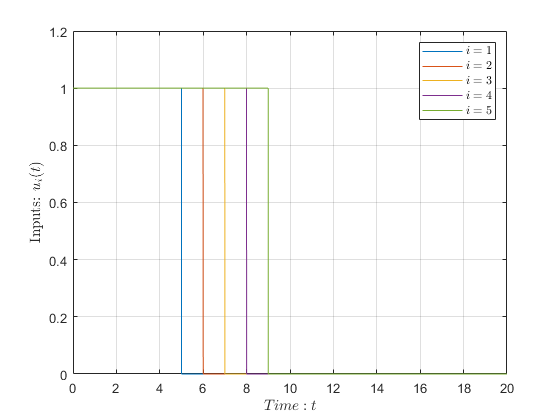

clear all
close all
clc


% This file is connected with the "JSimResultsModel2.slx" file
% Run this after running JSimResults.mlx ------> JSimResultsModel2.slx


load jPaperDataSimulation.mat
t_1 = 0;
t_2 = 20; %25
F_s = 1000; % Sampling freq 

% figure(1)
% network.drawNetwork(1,false);
% grid on

figure(1)
u = out.DataInputu(:,2:6);
t = out.DataInputu(:,1);
plot(t,u)
ylabel('Inputs: $u_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,0,1.2])

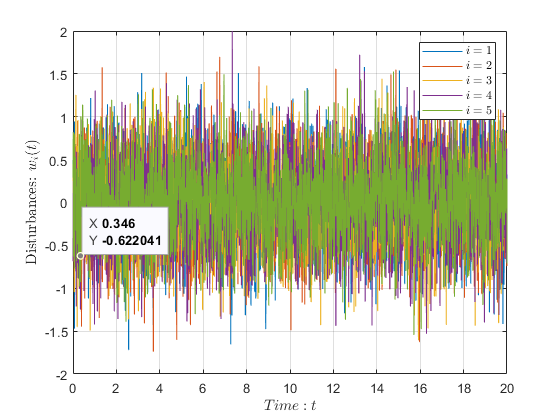



figure(2)
w = out.DataDisturbancew(:,2:6);
t = out.DataDisturbancew(:,1);
plot(t,w)
ylabel('Disturbances: $w_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-2,2])

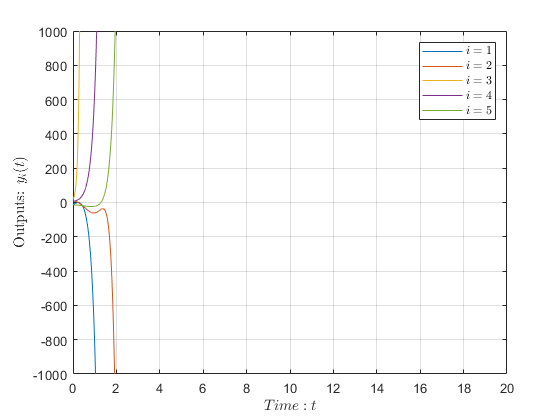



figure(3)
y = out.DataOpenLoop(:,2:6);
t = out.DataOpenLoop(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-1000,1000])

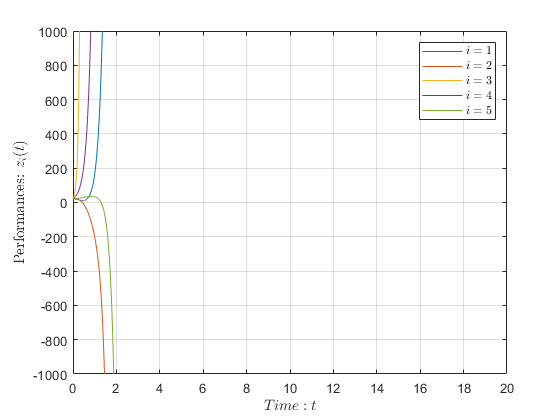


figure(4)
z = out.DataPerformancez(:,2:6);
t = out.DataPerformancez(:,1);
plot(t,z)
ylabel('Performances: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-1000,1000])

Stabilization Aspects: Centralized vs Decentralized

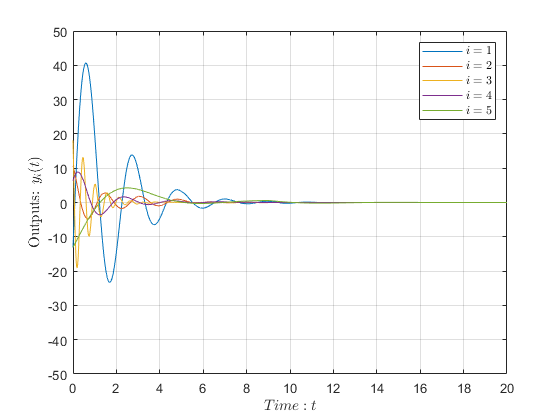

% Stabilization FSF
figure(5)
y = out.DataCentStabFSF(:,2:6);
t = out.DataCentStabFSF(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-50,50])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 1.1209

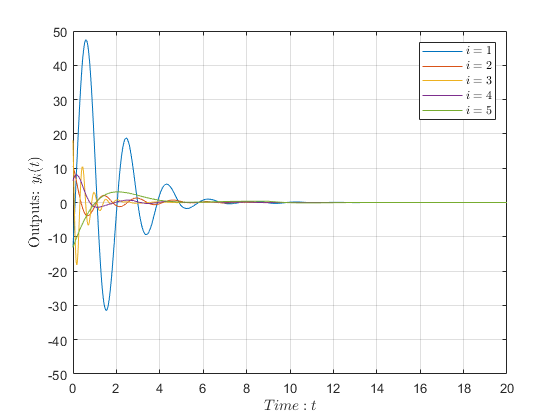


figure(6)
y = out.DataDecentStabFSF(:,2:6);
t = out.DataDecentStabFSF(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-50,50])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 1.0627

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 5.1868

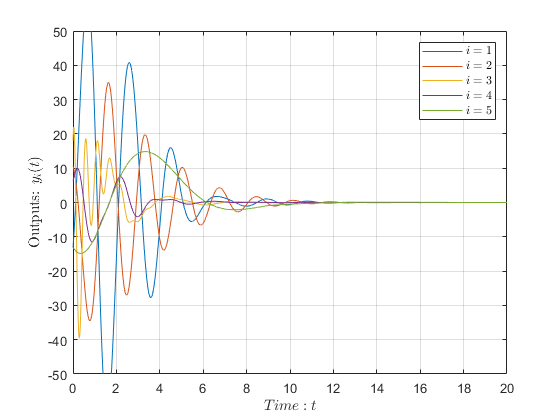



% Stabilization FSF+Obs
figure(7)
y = out.DataCentStabObs(:,2:6);
t = out.DataCentStabObs(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-50,50])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 3.4128

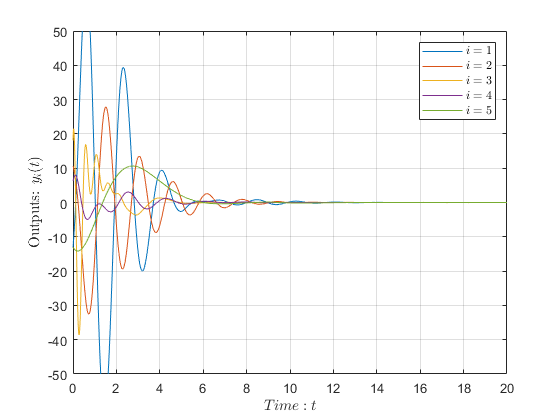


figure(8)
y = out.DataDecentStabObs(:,2:6);
t = out.DataDecentStabObs(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-50,50])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 2.4977

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 26.8117

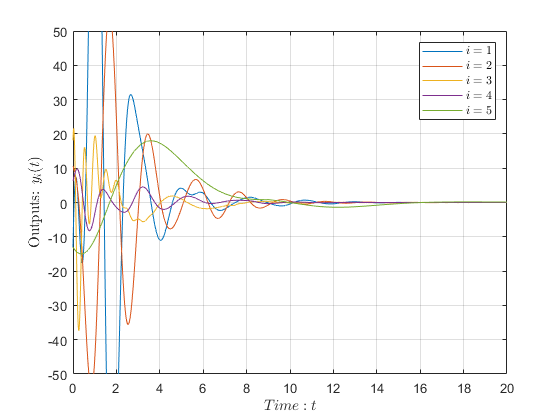



% Stabilization DOF
figure(9)
y = out.DataCentStabDOF(:,2:6);
t = out.DataCentStabDOF(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-50,50])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 4.2274

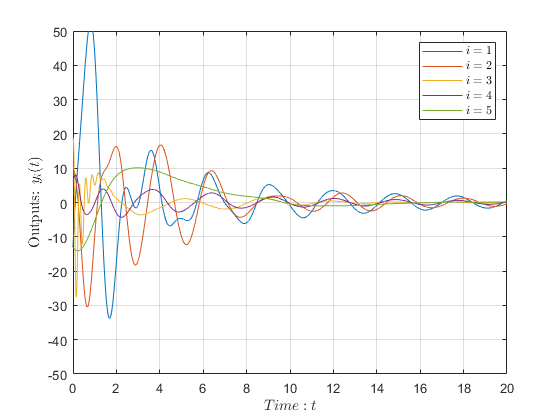


figure(10)
y = out.DataDecentStabDOF(:,2:6);
t = out.DataDecentStabDOF(:,1);
plot(t,y)
ylabel('Outputs: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-50,50])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 3.1074

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 26.4934

Performance: Dissipativity based improvement: Stability vs Dissipativity

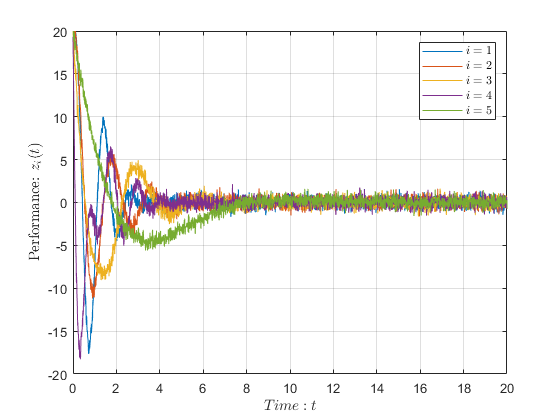

% Centralized FSF+Obs
figure(11)
z = out.DataCentStabObsError(:,2:6);
t = out.DataCentStabObsError(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-20,20])

MAP1 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP1 = 1.3268

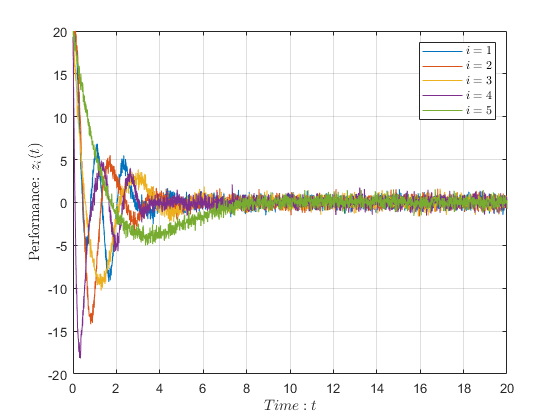


figure(12)
z = out.DataCentDissObsError(:,2:6);
t = out.DataCentDissObsError(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-20,20])

MAP2 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP2 = 1.2457

MAPImprovementPercentage = -(MAP2-MAP1)*100/MAP1

MAPImprovementPercentage = 6.1124

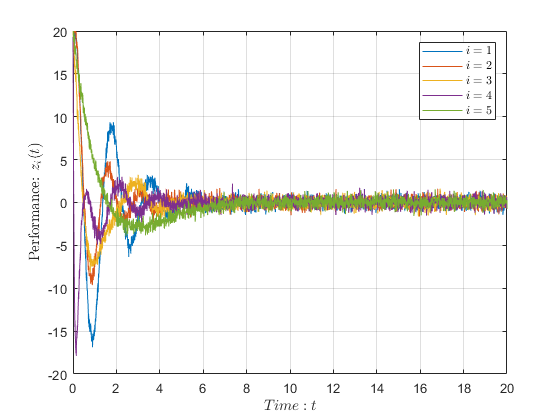



% Decentralized FSF+Obs
figure(13)
z = out.DataDecentStabObsError(:,2:6);
t = out.DataDecentStabObsError(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-20,20])

MAP1 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP1 = 1.1550

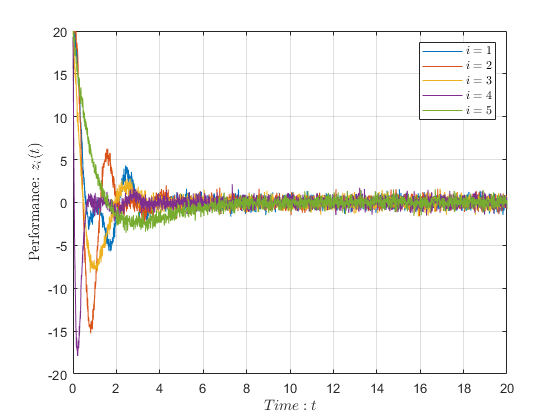


figure(14)
z = out.DataDecentDissObsError(:,2:6);
t = out.DataDecentDissObsError(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-20,20])

MAP2 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP2 = 1.0153

MAPImprovementPercentage = -(MAP2-MAP1)*100/MAP1

MAPImprovementPercentage = 12.1010

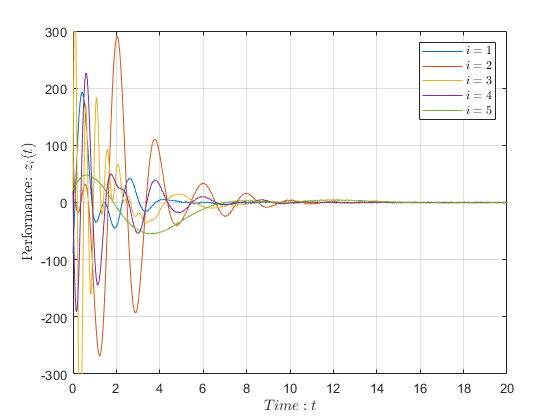



% Centralized DOF
figure(15)
z = out.DataCentStabDOFPerf(:,2:6);
t = out.DataCentStabDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP1 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP1 = 16.0107

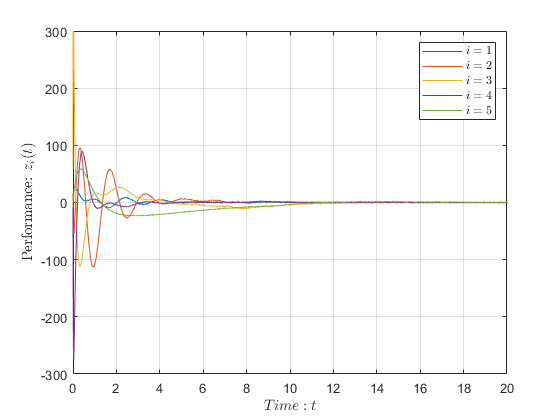



figure(16)
z = out.DataCentDissDOFPerf(:,2:6);
t = out.DataCentDissDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP2 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP2 = 5.9660

MAPImprovementPercentage = -(MAP2-MAP1)*100/MAP1

MAPImprovementPercentage = 62.7372

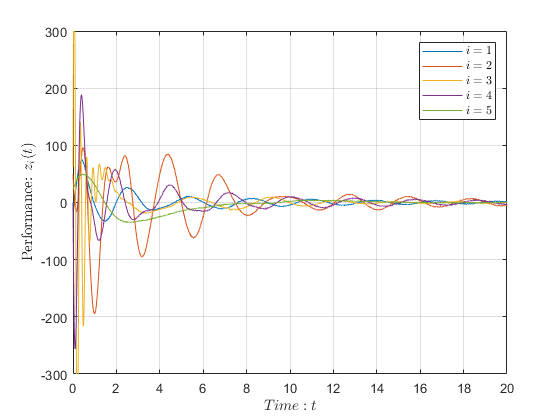



% Decentralized DOF
figure(17)
z = out.DataDecentStabDOFPerf(:,2:6);
t = out.DataDecentStabDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP1 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP1 = 13.3650

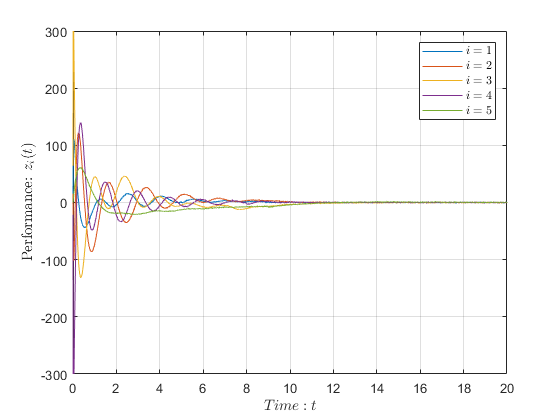


figure(18)
z = out.DataDecentDissDOFPerf(:,2:6);
t = out.DataDecentDissDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP2 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP2 = 7.3233

MAPImprovementPercentage = -(MAP2-MAP1)*100/MAP1

MAPImprovementPercentage = 45.2053

(Testing, omit these) Output: Dissipativity based improvement: Stability vs Dissipativity

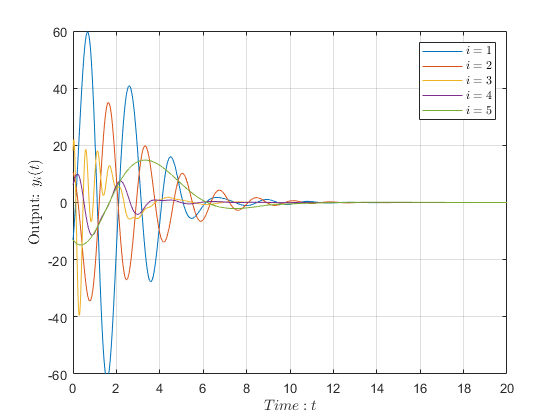

% Centralized FSF+Obs
figure(19)
y = out.DataCentStabObs(:,2:6);
t = out.DataCentStabObs(:,1);
plot(t,y)
ylabel('Output: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 3.4128

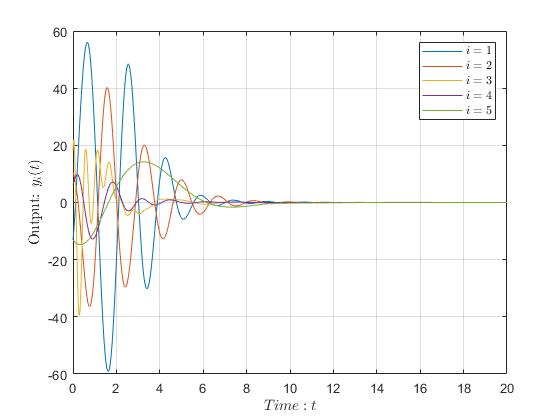


figure(20)
y = out.DataCentDissObs(:,2:6);
t = out.DataCentDissObs(:,1);
plot(t,y)
ylabel('Output: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 3.2615

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 4.4308

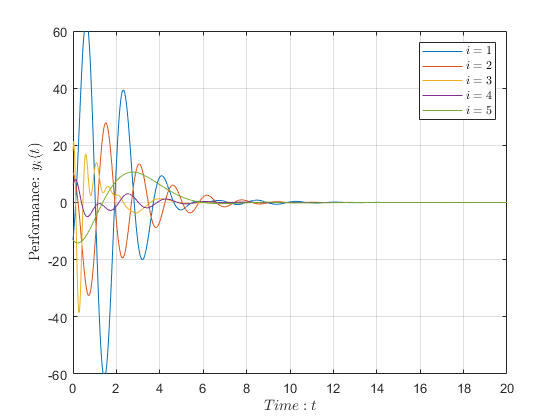


% Decentralized FSF+Obs
figure(21)
y = out.DataDecentStabObs(:,2:6);
t = out.DataDecentStabObs(:,1);
plot(t,y)
ylabel('Performance: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 2.4977

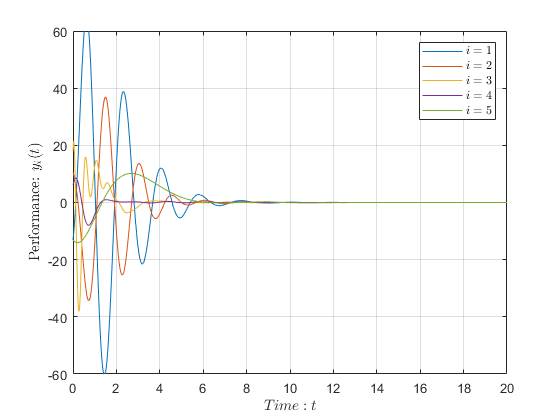


figure(22)
y = out.DataDecentDissObs(:,2:6);
t = out.DataDecentDissObs(:,1);
plot(t,y)
ylabel('Performance: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 2.4926

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 0.2043

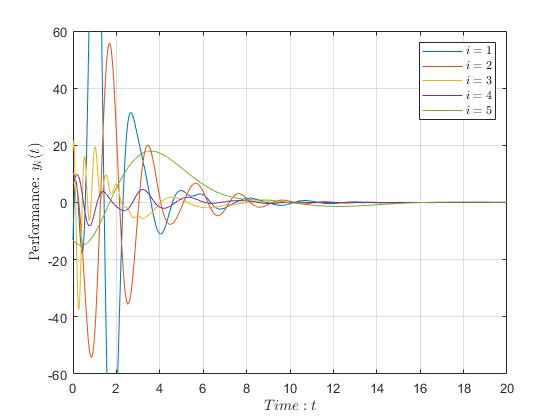



% Centralized DOF
figure(23)
y = out.DataCentStabDOF(:,2:6);
t = out.DataCentStabDOF(:,1);
plot(t,y)
ylabel('Performance: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 4.2274

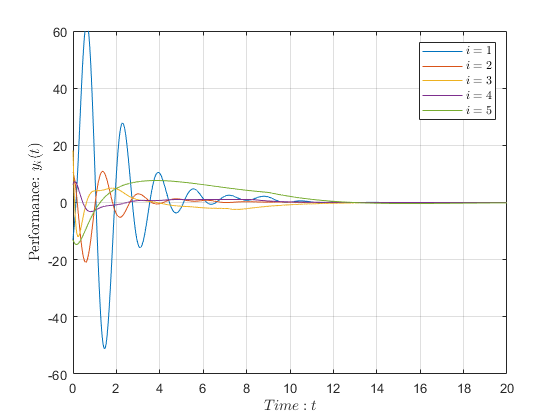


figure(24)
y = out.DataCentDissDOF(:,2:6);
t = out.DataCentDissDOF(:,1);
plot(t,y)
ylabel('Performance: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 2.2420

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 46.9646

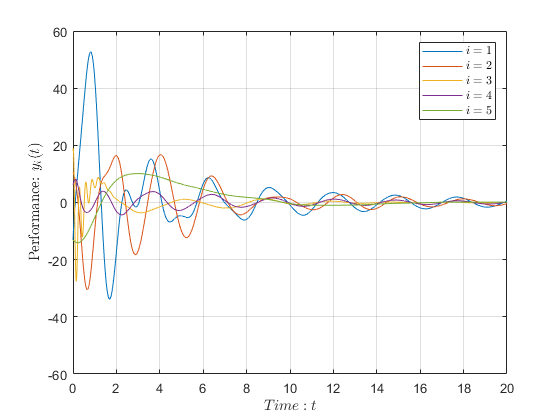


% Decentralized DOF
figure(25)
y = out.DataDecentStabDOF(:,2:6);
t = out.DataDecentStabDOF(:,1);
plot(t,y)
ylabel('Performance: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 3.1074

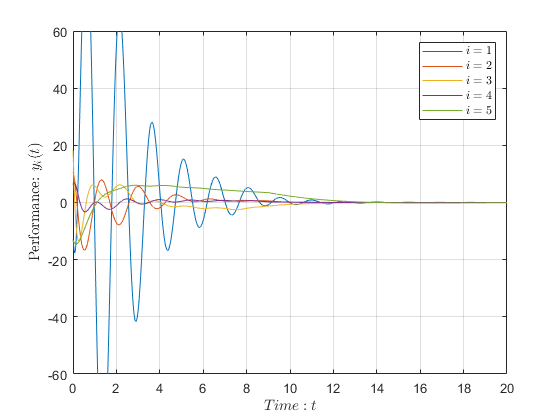


figure(26)
y = out.DataDecentDissDOF(:,2:6);
t = out.DataDecentDissDOF(:,1);
plot(t,y)
ylabel('Performance: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 3.0726

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 1.1205

Disturbance Rejection: DOF for y(t) and z(t)

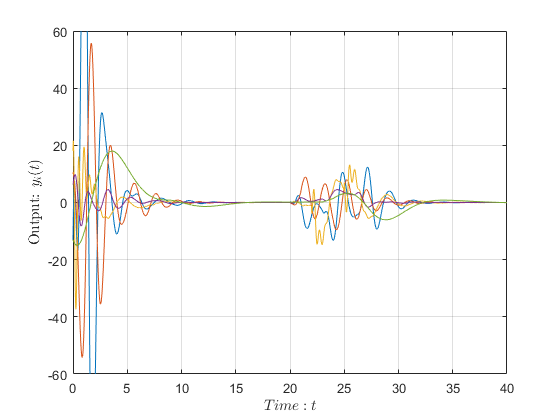

load jPaperDataSimulationWithDist.mat
t_1 = 0;
t_2 = 40;

% Output: Centralized DOF
figure(27)
y = out.DataCentStabDOF(:,2:6);
t = out.DataCentStabDOF(:,1);
plot(t,y)
ylabel('Output: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 2.9778

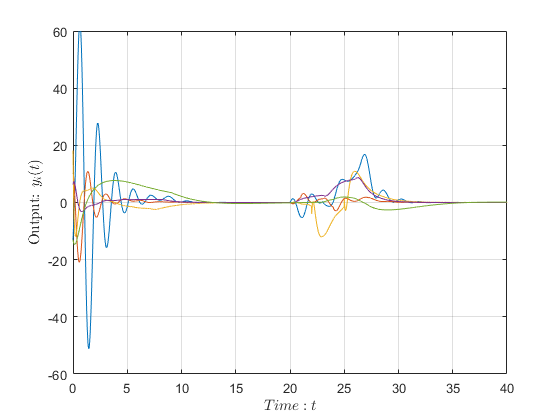


figure(28)
y = out.DataCentDissDOF(:,2:6);
t = out.DataCentDissDOF(:,1);
plot(t,y)
ylabel('Output: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 1.8900

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = 36.5286

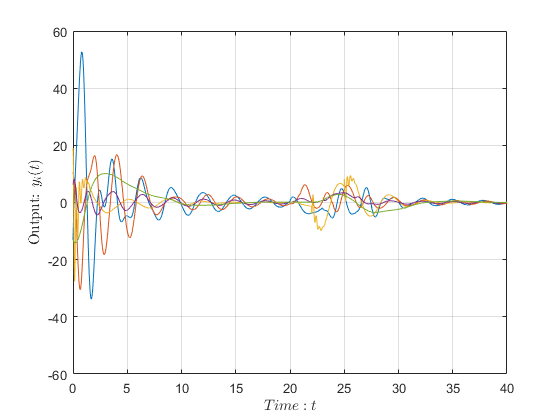


% Output: Decentralized DOF
figure(29)
y = out.DataDecentStabDOF(:,2:6);
t = out.DataDecentStabDOF(:,1);
plot(t,y)
ylabel('Output: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO1 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO1 = 2.2188

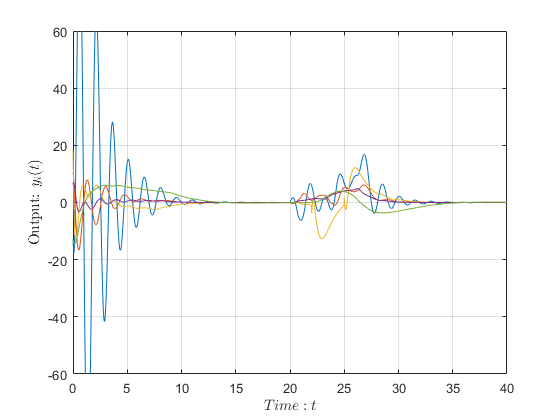


figure(30)
y = out.DataDecentDissDOF(:,2:6);
t = out.DataDecentDissDOF(:,1);
plot(t,y)
ylabel('Output: $y_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-60,60])

MAO2 = mean(mean(abs(y(t_1*F_s+1:t_2*F_s,:))))

MAO2 = 2.3695

MAOImprovementPercentage = -(MAO2-MAO1)*100/MAO1

MAOImprovementPercentage = -6.7905

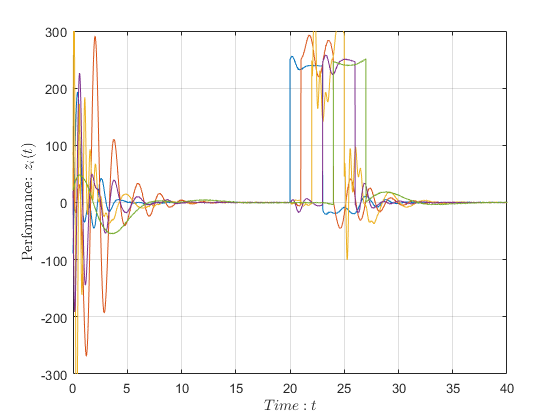



% Perf: Centralized DOF
figure(31)
z = out.DataCentStabDOFPerf(:,2:6);
t = out.DataCentStabDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP1 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP1 = 28.9752

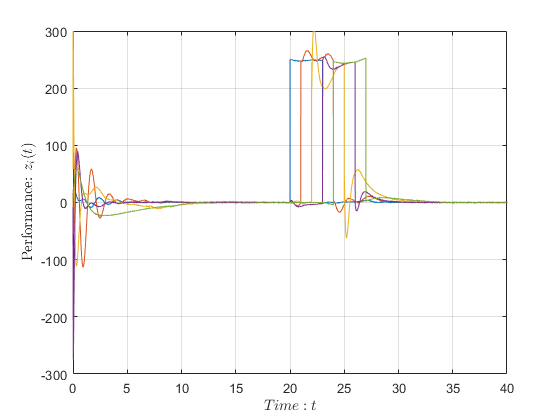



figure(32)
z = out.DataCentDissDOFPerf(:,2:6);
t = out.DataCentDissDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP2 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP2 = 22.6994

MAPImprovementPercentage = -(MAP2-MAP1)*100/MAP1

MAPImprovementPercentage = 21.6591

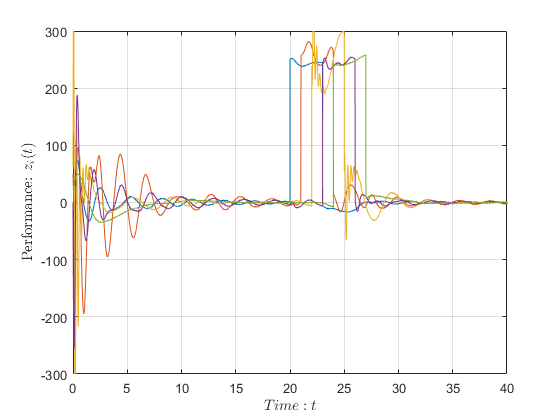



% Perf: Decentralized DOF
figure(33)
z = out.DataDecentStabDOFPerf(:,2:6);
t = out.DataDecentStabDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP1 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP1 = 27.2643

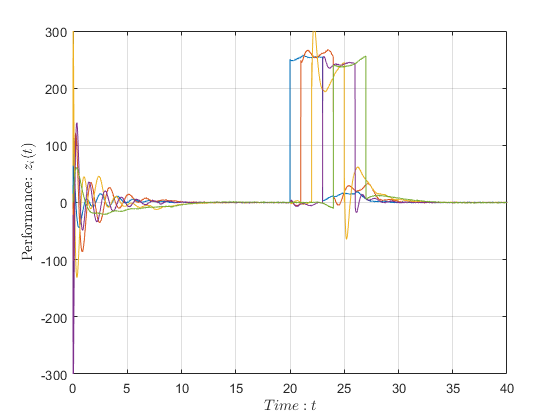


figure(34)
z = out.DataDecentDissDOFPerf(:,2:6);
t = out.DataDecentDissDOFPerf(:,1);
plot(t,z)
ylabel('Performance: $z_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
% legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-300,300])

MAP2 = mean(mean(abs(z(t_1*F_s+1:t_2*F_s,:))))

MAP2 = 24.0450

MAPImprovementPercentage = -(MAP2-MAP1)*100/MAP1

MAPImprovementPercentage = 11.8079

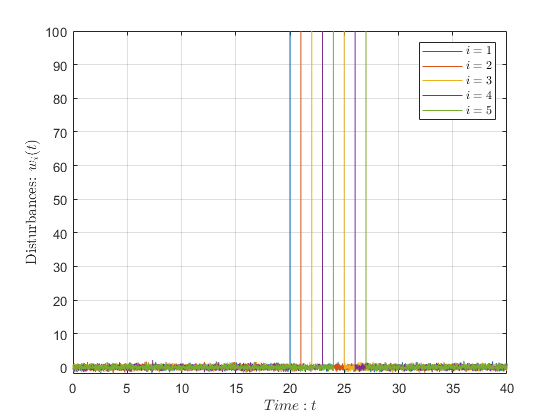




figure(35)
w = out.DataDisturbancew(:,2:6);
t = out.DataDisturbancew(:,1);
plot(t,w)
ylabel('Disturbances: $w_i(t)$','interpreter','latex')
xlabel('$Time: t$','interpreter','latex')
legend('$i=1$','$i=2$','$i=3$','$i=4$','$i=5$','interpreter','latex')
grid on
axis([t_1,t_2,-2,100])